# **制御器の付加**

**本ファイルでは電力システムにコントローラをつけてシミュレーションを行う方法を説明します。**

**制御器を付加せずに各種解析を行う場合は本stepはスキップして構いません。**

**以下の赤枠で囲った部分の作業に対応します。**

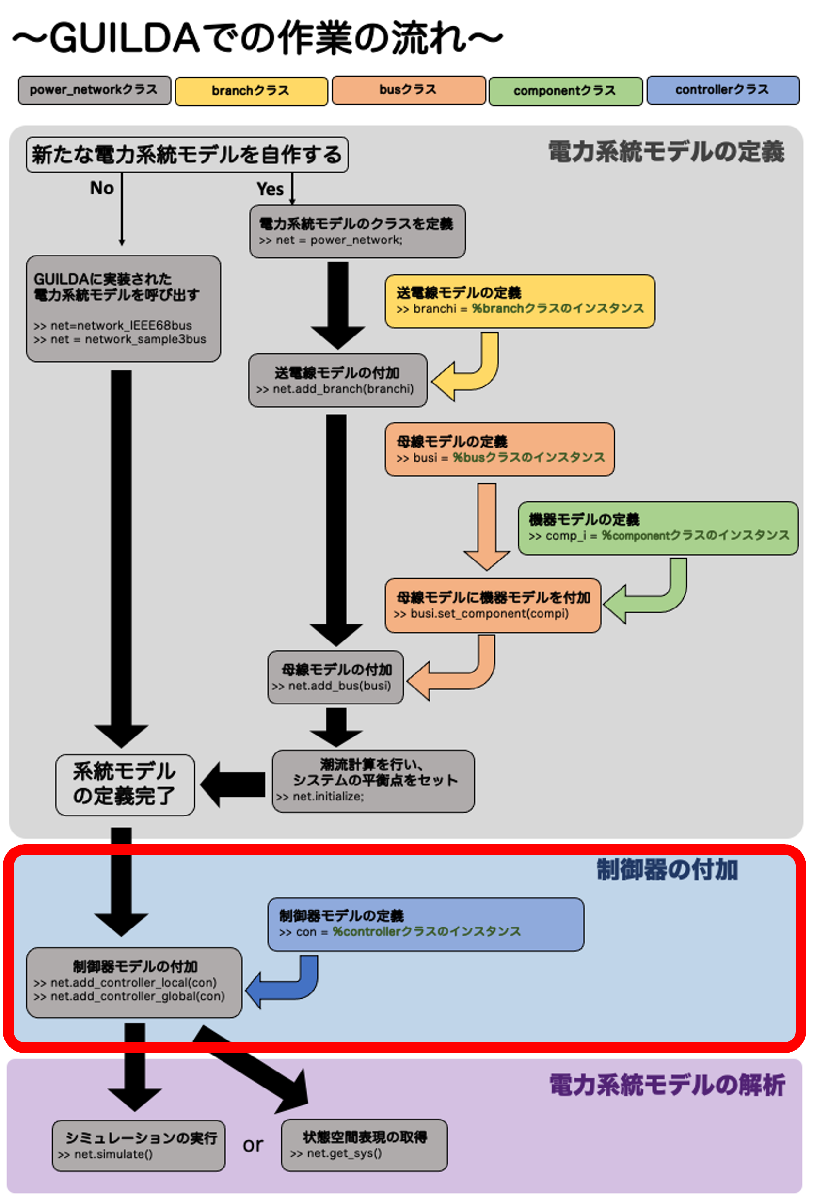

## **電力ネットワークの定義**

ひとまずシミュレーション対象となる電力ネットワークを作成します。

詳しくは、「[Step1_BuildNetwork](matlab:open('./Step1_BuildNetwork.mlx'))」を参照してください。

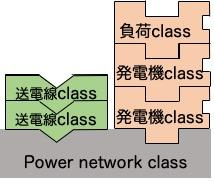

### ・実装方法

 
% IEEE68busモデルを使用
net = network.IEEE68bus;

## **コントローラの定義**

### **・コントローラの概要**

GUILDAではいくつかのコントローラが利用できますが、共通して次のように定義できます。

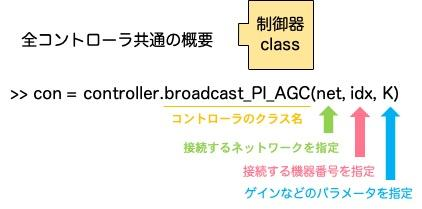

### ・コントローラの種類

- AGCコントローラ：詳しくは「[Controller_AGC](matlab:open('./ClassManual/Controller_AGC.mlx'))」を参照

- LQRコントローラ：詳しくは「[Controller_LQR](matlab:open('./ClassManual/Controller_LQR.mlx'))」を参照

- レトロフィットコントローラ：詳しくは「[Controller_Retrofit](matlab:open('./ClassManual/Controller_Retrofit.mlx'))」を参照

- 自分でコントローラを作る：詳しくは「[Controller_Abstract](matlab:open('./ClassManual/Controller_Abstract.mlx'))」を参照

### ・実装方法

ここでは、具体的にAGCコントローラを定義する際のコードを載せます。

 
% AGCを定義
con = controller.broadcast_PI_AGC(net,1:16,1:16,-5,-500);

## **コントローラの付加**

作成したコントローラを電力ネットワークに付加します。

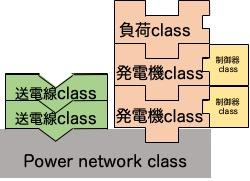

### ・実装方法

 
% 制御器を付加する
net.add_controller_global(con);

## **シミュレーションの実行**

最後にコントローラをつけた電力ネットワークでシミュレーションを行います。

シミュレーションの実行についての詳細は「[Step3_SimulateCondition](matlab:open('./Step3_SimulateCondition.mlx'))」を、プロットについては「[Step4_SimulateResultData](matlab:open('./Step4_SimulateResultData.mlx'))」を参照してください。

### ・実装方法

 
% シミュレーション
out = net.simulate([0,5],'fault',{{[1,1.01],1}});
 
% シミュレーション結果のプロット
out.plot('para', 'omega')

`以上で電力系統モデルを定義し、制御器を付加することができました。`

`次のステップでは、この電力システムの定常潮流状態や平衡点などのデータの読み方を解説します。`

[](matlab:open('./Step1_BuildNetwork.mlx'))　　[](matlab:open('./Step3_NetProperties.mlx'))